## Set parameters

In this script we will demonstrate scattering of an incident plane wave with direction $(1,0)$ and wavelength $\lambda$ by circular scatterers with radius $\rho$ using the tmatsolver class.

First we will setup the parameters $\lambda$ and $\rho$ that determine the scattering problem.

lambda = 2;

rho = 1;

Note: in the code we will represent vectors $(x,y)$ by complex numbers $x + yi$.

## Set dependent parameters

Set the wavenumber based on the incident wavelength

        $k = \frac{2 \pi}{\lambda}$.

kwave = 2*pi/lambda;

This is also a good time to setup the incident wave $u^{inc}(\mathbf{x}) = e^{i k \mathbf{x} \cdot (1,0)}$ with direction $(\cos 0,\sin 0)$:

uinc = plane_wave(0,kwave);

## Setup the scattering problem

We can setup an array of scatterer types eg sound-soft disk, sound-hard disk etc.

types = [sound_soft_disk(kwave,rho),...
    sound_hard_disk(kwave,rho)];

Next we setup a tmatsolver object, which will handle the multiple scattering simulations for us. First we will have a configuration with two type-1 scatterers located at (0,3) and (0,-3).

obj = tmatsolver(uinc,particle(types(1),3i),...
    particle(types(1),-3i));

This is a good time to draw a schematic of the scattering problem.

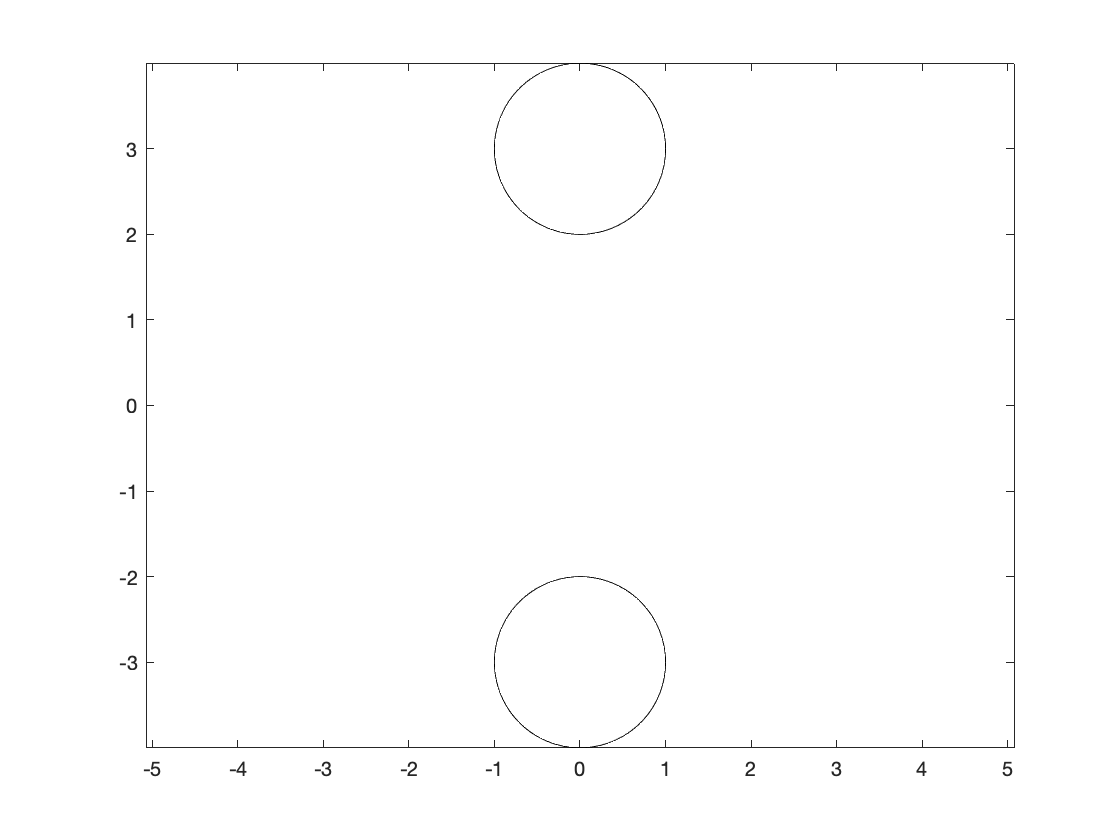

obj.schematic()
axis equal

## Solve the scattering problem and visualise the solution

Now we can solve the scattering problem. The solution is stored within obj and we can subsequently use it for plotting of evaluating the field.

obj.solve()

Let us visualise the total field on the domain $[-L,L] \times [-L,L]$.

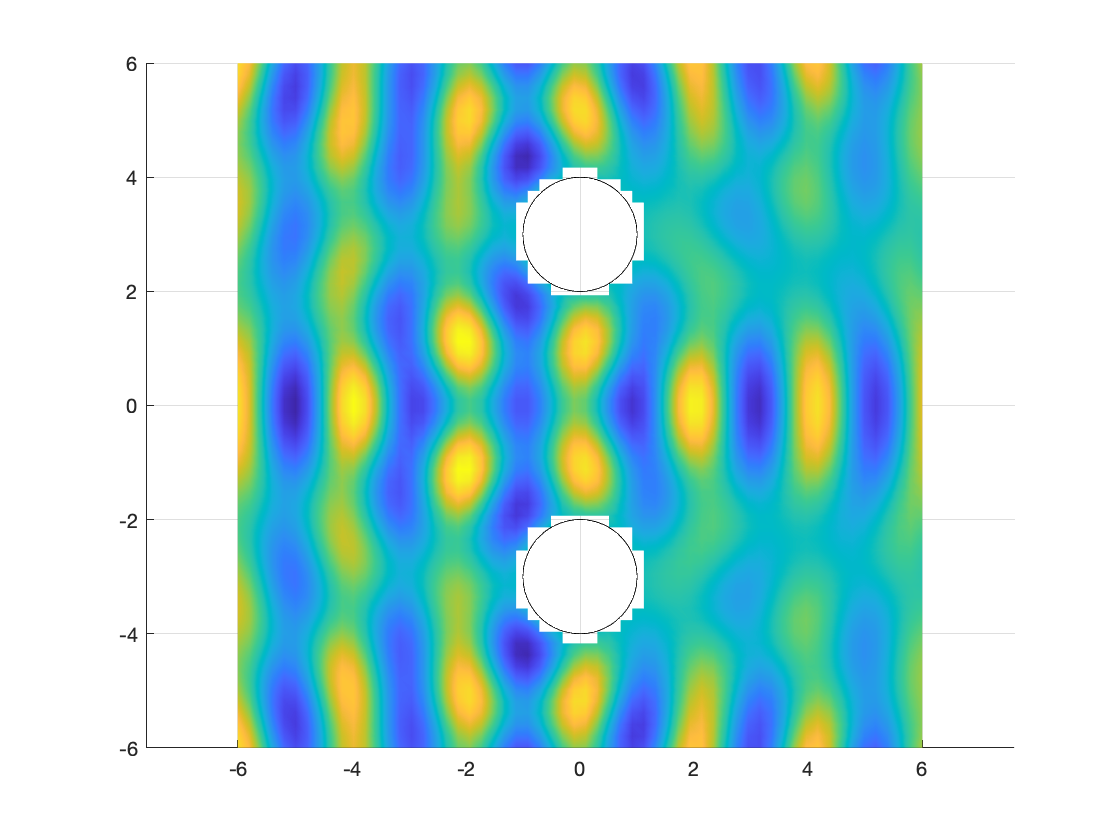

L = 6;
figure
obj.plot([-L L -L L])

If we prefer, we can produce a movie instead.

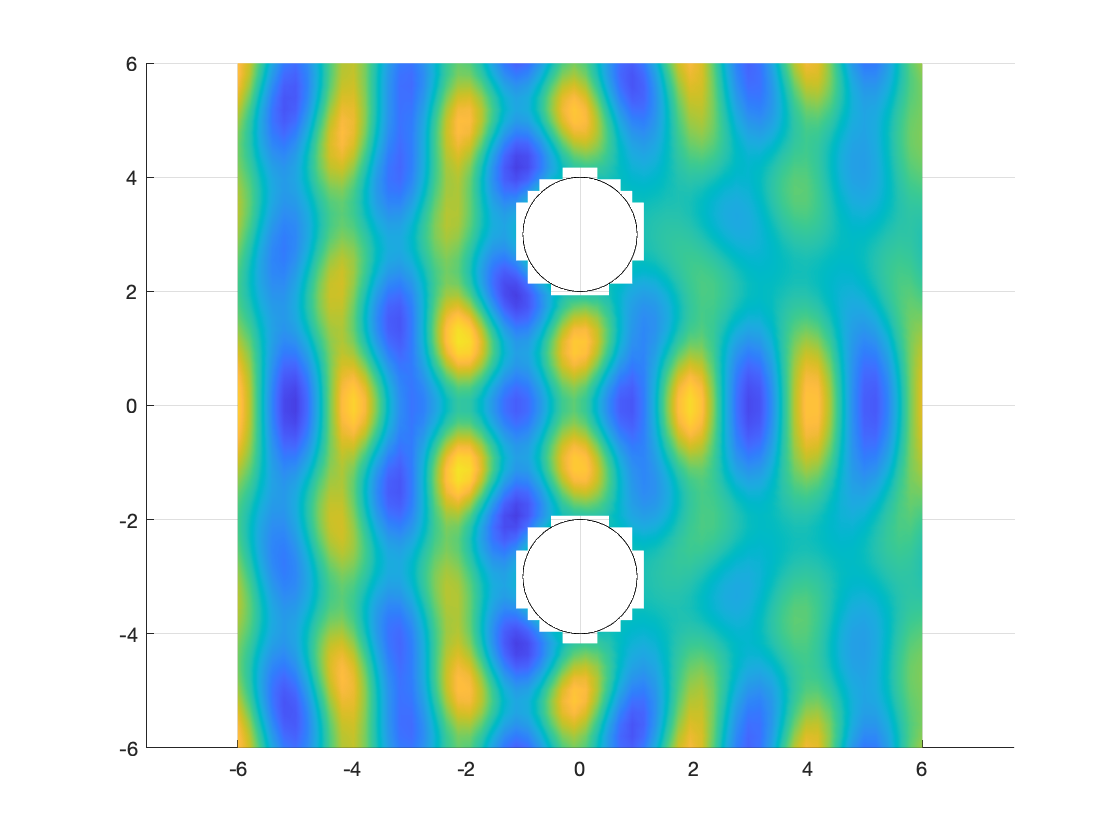

figure
m = obj.movie([-L L -L L]);

The movie can be exported in GIF format and used eg in webpages, or social media.

m.export('sample.gif','gif')

## Mixed configurations

Let us do a similar simulation, but this time with a mixed configuration contatining one type-1 particle and one type-2 particle.

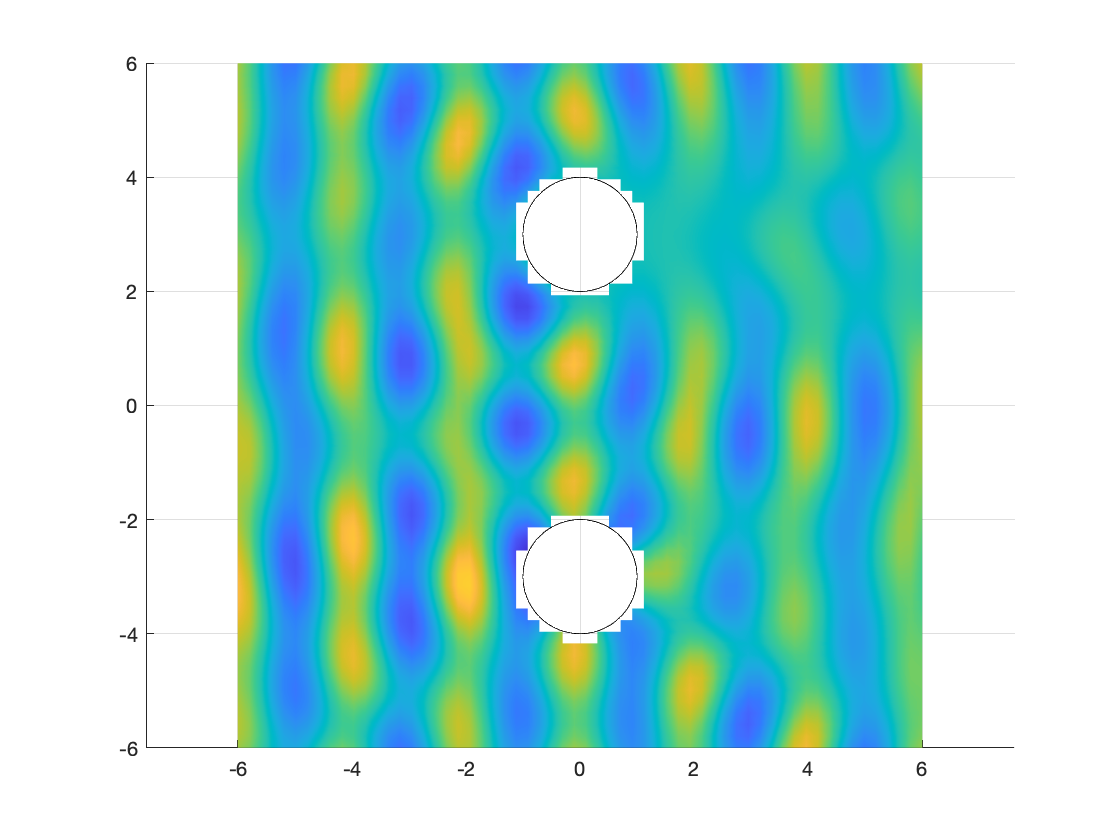

% note that the second particle is of type-2
obj = tmatsolver(uinc,particle(types(1),3i),...
    particle(types(2),-3i));

obj.solve()

L = 6;

figure

m = obj.movie([-L L -L L]);

## Configurations with arbitrary numbers of scatterers

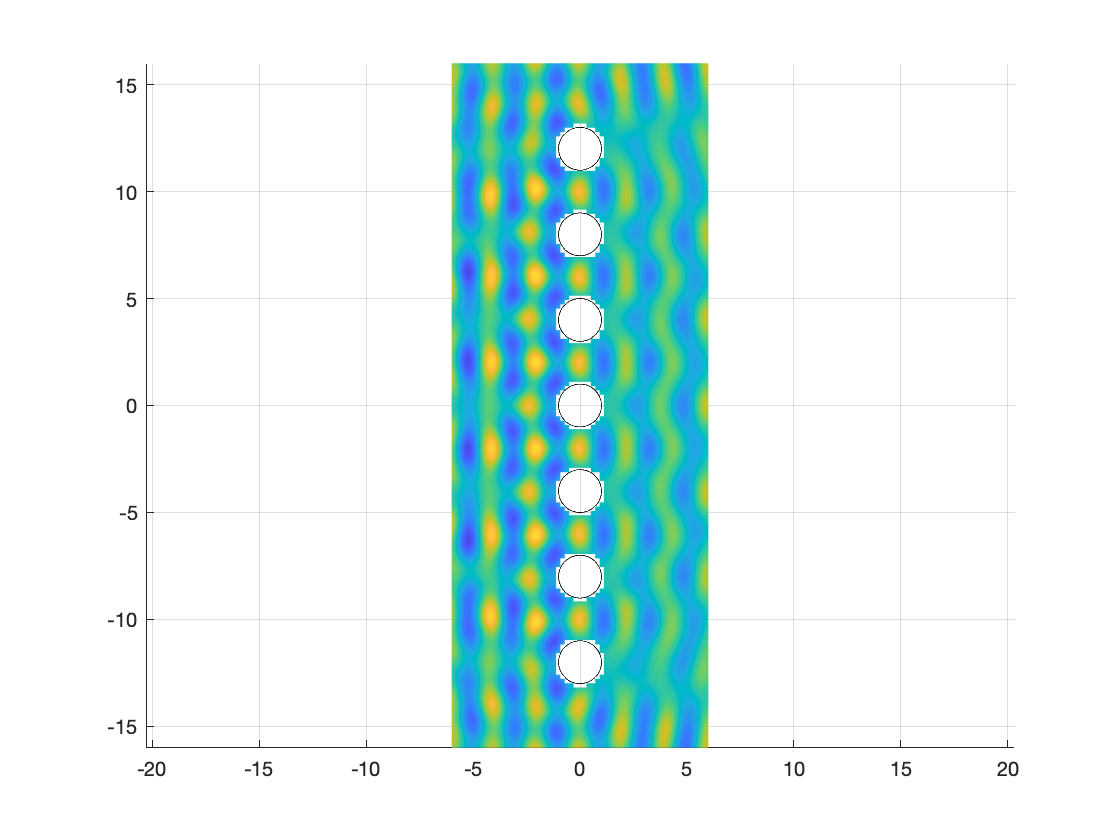

pos = 1i * (-12:4:12);

% note that the solver is instantiated with only the incident 
% wave... the scatterers are added later
obj = tmatsolver(uinc);

for j=1:length(pos)
    obj.addParticle(particle(types(1),pos(j)));
end

obj.solve()

L = 6;

figure

m = obj.movie([-L L -16 16]);